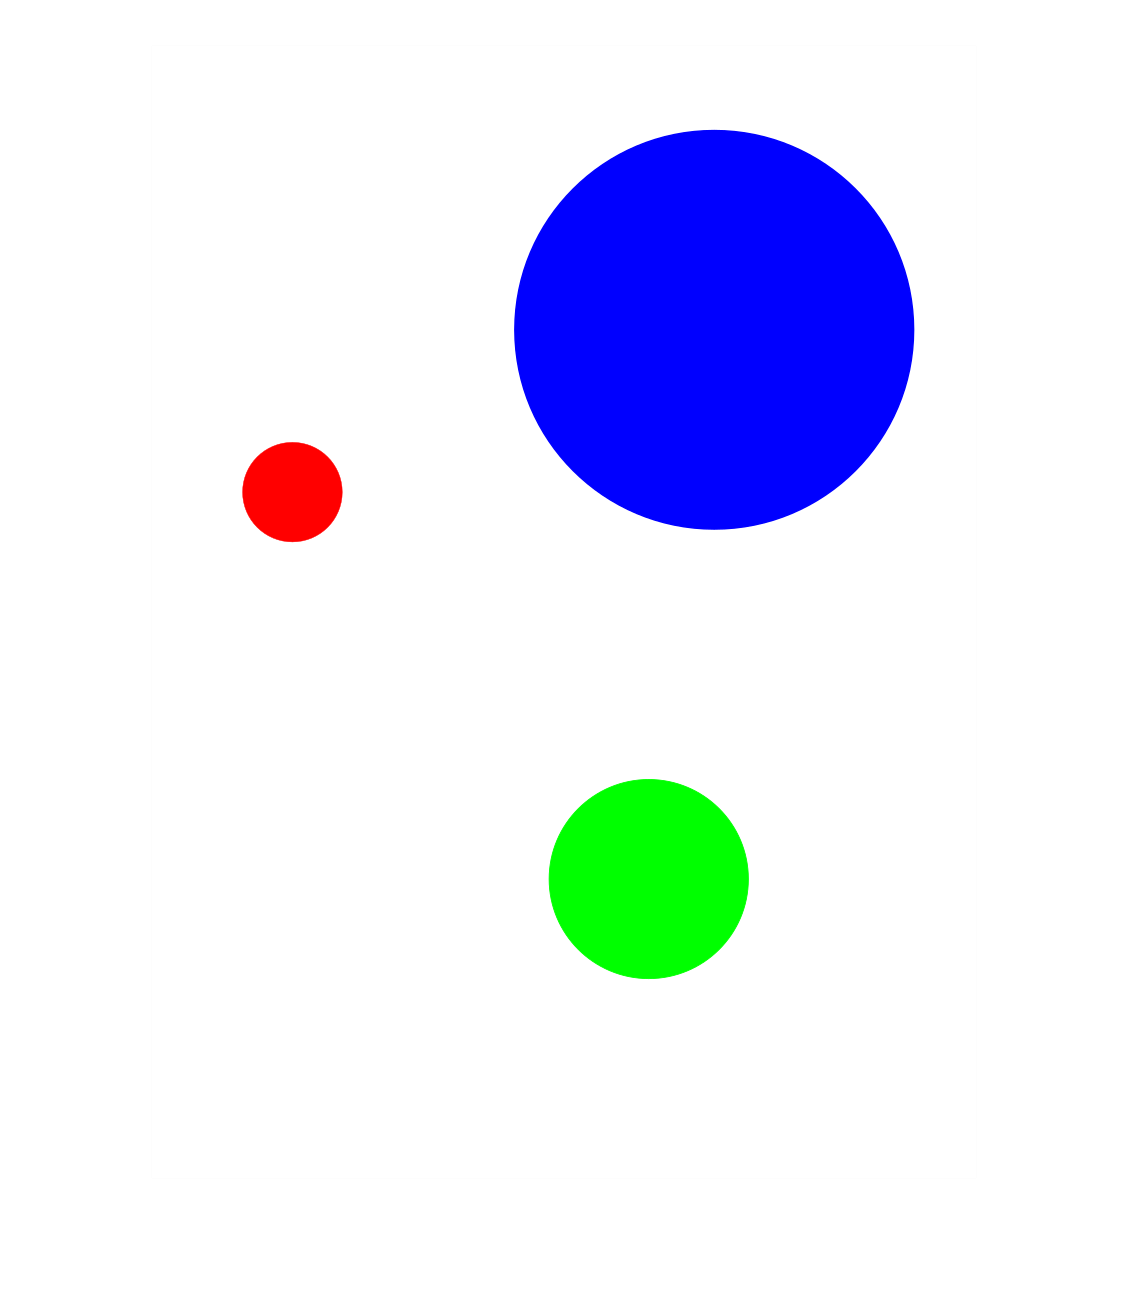

clear
clc

img = imread("radiusDots.png");
imshow(img)


%Calculate the distance between the center of red and green circles

%Red Circle
redCircle = img;
m = redCircle(:,:,1)>128 & redCircle(:,:,2)<128 & redCircle(:,:,3)<128;
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
redCircle(~m3) = 255;
%Convert for calculations
redCircle = double(redCircle());
%Grayscale for edge detection
gLayer = uint8( (redCircle(:,:,1)+redCircle(:,:,2)+redCircle(:,:,3))/3 );
%Find Center
[~, redCx] = min(sum(gLayer));
[~, redCy] = min(sum(gLayer'));
fprintf('Red Center is at (%d, %d).\n', redCx, redCy)

Red Center is at (142, 448).



%Green Circle
greenCircle = img;
m = greenCircle(:,:,1)<128 & greenCircle(:,:,2)>128 & greenCircle(:,:,3)<128;
m3(:,:,1) = m;
m3(:,:,2) = m;
m3(:,:,3) = m;
greenCircle(~m3) = 255;
%Convert for calculations
greenCircle = double(greenCircle());
%Grayscale for edge detection
gLayer = uint8( (greenCircle(:,:,1)+greenCircle(:,:,2)+greenCircle(:,:,3))/3 );
%Find Center
[~, greenCx] = min(sum(gLayer));
[~, greenCy] = min(sum(gLayer'));
fprintf('Green Center is at (%d, %d).\n', greenCx, greenCy)

Green Center is at (496, 835).



%Calculate Distance
distanceRG = sqrt( (redCx-greenCx)^2 + (redCy-greenCy)^2 )

distanceRG = 524.4855